clear;
clc;
close all;

## Setup the initial parameters and file paths

NumCandidateRelays = [1152, 2384, 3644];
NumCandidateRelaysString = ["1152","2384","3644"];
BeamWidth = [5,7,9,11,13,15];
DataClass = ["Capacity","Paths","Sequence"];
PathResult1Mbs = '../../Data/Paths/Single_MBS/200/';
PathResult2Mbs = '../../Data/Paths/Double_MBS/200/';
PathResult1Mbs300m = '../../Data/Paths/Single_MBS/300/';
PathResult2Mbs300m = '../../Data/Paths/Double_MBS/300/';
PathResult1MbsLA = '../../Data/Paths/Single_MBS_LimitedArea/200/';
PathResult2MbsLA = '../../Data/Paths/Double_MBS_LimitedArea/200/';
PathResultBench = '../../Data/Paths/Idp/200/';
PathResultBench300m = '../../Data/Paths/Idp/300/';

## Read data from files

Data1Mbs = ReadDataFromFiles(PathResult1Mbs);
Data2Mbs = ReadDataFromFiles(PathResult2Mbs);
Data1MbsLA = ReadDataFromFiles(PathResult1MbsLA);
Data2MbsLA = ReadDataFromFiles(PathResult2MbsLA);
Data1Mbs300m = ReadDataFromFiles(PathResult1Mbs300m);
Data2Mbs300m = ReadDataFromFiles(PathResult2Mbs300m);
Data1MbsBench = ReadDataFromFiles(PathResultBench);
Data1MbsBench300m = ReadDataFromFiles(PathResultBench300m);

## Calculate the average relay number per logical link

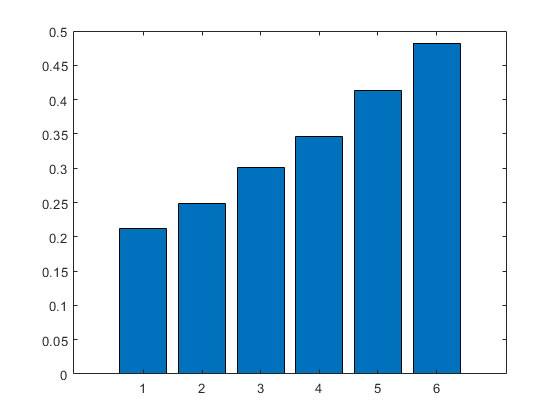

AvgRNum1Mbs = Data1Mbs(:,:,2)./Data1Mbs(:,:,1);
AvgRNum2Mbs300m = Data2Mbs300m(:,:,2)./Data2Mbs300m(:,:,1);
AvgRNum1MbsBench = Data1MbsBench(:,:,2)./Data1MbsBench(:,:,1);
AvgRNum1MbsBench300m = Data1MbsBench300m(:,:,2)./Data1MbsBench300m(:,:,1);

AvgRNum1MbsLow = zeros(1,6);
AvgRNum1MbsBenchLow = zeros(1,6);
AvgRNum1MbsMed = zeros(1,6);
AvgRNum1MbsBenchMed = zeros(1,6);
AvgRNum1MbsHigh = zeros(1,6);
AvgRNum1MbsBenchHigh = zeros(1,6);
for i = 1:6
    result = calculateAverageRelayNum(AvgRNum1Mbs(1:100,i), AvgRNum1MbsBench(1:100,i));
    AvgRNum1MbsLow(i) = result(1);
    AvgRNum1MbsBenchLow(i) = result(2);
    result = calculateAverageRelayNum(AvgRNum1Mbs(101:200,i), AvgRNum1MbsBench(101:200,i));
    AvgRNum1MbsMed(i) = result(1);
    AvgRNum1MbsBenchMed(i) = result(2);
%     result = calculateAverageRelayNum(AvgRNum1Mbs(201:300,i), AvgRNum1MbsBench(201:300,i));
%     AvgRNum1MbsHigh(i) = result(1);
%     AvgRNum1MbsBenchHigh(i) = result(2);
end
bar((AvgRNum1MbsLow-AvgRNum1MbsBenchLow)./AvgRNum1MbsBenchLow)

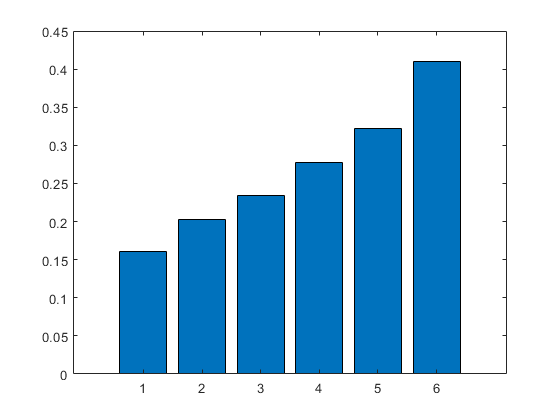

bar((AvgRNum1MbsMed-AvgRNum1MbsBenchMed)./AvgRNum1MbsBenchMed)

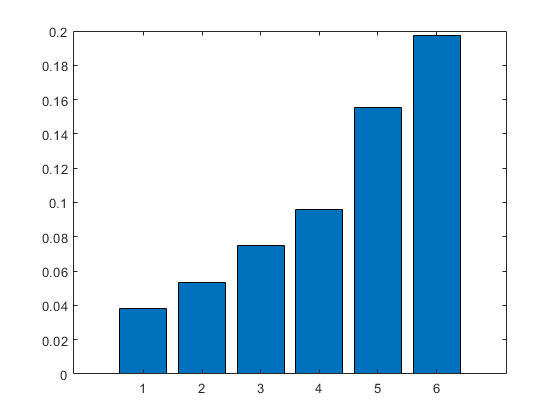


AvgRNum2Mbs300mLow = zeros(1,6);
AvgRNum1MbsBench300mLow = zeros(1,6);
AvgRNum2Mbs300mMed = zeros(1,6);
AvgRNum1MbsBench300mMed = zeros(1,6);
AvgRNum2Mbs300mHigh = zeros(1,6);
AvgRNum1MbsBench300mHigh = zeros(1,6);
for i = 1:6
    result = calculateAverageRelayNum(AvgRNum2Mbs300m(1:100,i), AvgRNum1MbsBench300m(1:100,i));
    AvgRNum2Mbs300mLow(i) = result(1);
    AvgRNum1MbsBench300mLow(i) = result(2);
    result = calculateAverageRelayNum(AvgRNum2Mbs300m(101:200,i), AvgRNum1MbsBench300m(101:200,i));
    AvgRNum2Mbs300mMed(i) = result(1);
    AvgRNum1MbsBench300mMed(i) = result(2);
    result = calculateAverageRelayNum(AvgRNum2Mbs300m(201:300,i), AvgRNum1MbsBench300m(201:300,i));
    AvgRNum2Mbs300mHigh(i) = result(1);
    AvgRNum1MbsBench300mHigh(i) = result(2);
end
bar((AvgRNum2Mbs300mLow-AvgRNum1MbsBench300mLow)./AvgRNum1MbsBench300mLow)

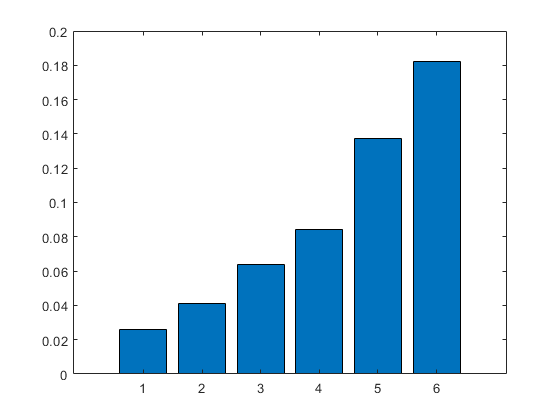

bar((AvgRNum2Mbs300mMed-AvgRNum1MbsBench300mMed)./AvgRNum1MbsBench300mMed)

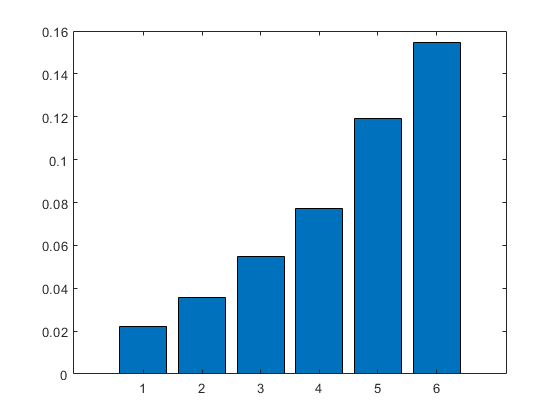

bar((AvgRNum2Mbs300mHigh-AvgRNum1MbsBench300mHigh)./AvgRNum1MbsBench300mHigh)

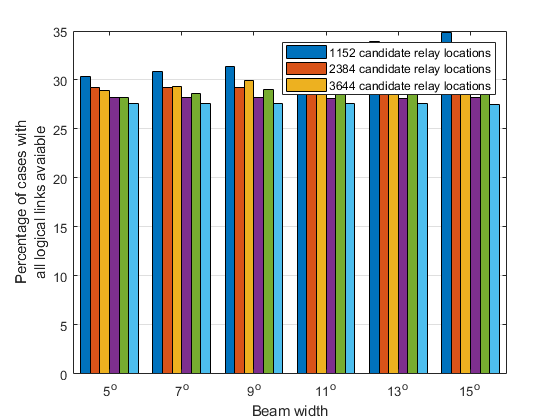

figure;
bw = 5:2:15;
% Data to be plotted as a bar graph
model_series = [AvgRNum2Mbs300mLow;AvgRNum1MbsBench300mLow;AvgRNum2Mbs300mMed;AvgRNum1MbsBench300mMed;AvgRNum2Mbs300mHigh;AvgRNum1MbsBench300mHigh]'.*22;
%Data to be plotted as the error bars
% model_error = [avgNumRelayStd;avgNumRelayIdpStd;avgNumRelayStd2;avgNumRelayIdpStd2]';
% Creating axes and the bar graph
ax = axes;
h = bar(model_series,'BarWidth',1);
% Set color for each bar face
% h(1).FaceColor = 'blue';
% h(2).FaceColor = 'yellow';
% Properties of the bar graph as required
ax.YGrid = 'on';
ax.GridLineStyle = '-';
xticks(ax,[1 2 3 4 5 6]);
% Naming each of the bar groups
xticklabels(ax,{ '5^o', '7^o', '9^o', '11^o', '13^o', '15^o'});
% ytickformat(ax, 'percentage');
% X and Y labels
xlabel ('Beam width');
ylabel ({'Percentage of cases with','all logical links avaiable'});
% Creating a legend and placing it outside the bar plot
lg = legend('1152 candidate relay locations','2384 candidate relay locations','3644 candidate relay locations','AutoUpdate','off');
% lg.Location = 'BestOutside';
lg.Orientation = 'vertical';
hold on;

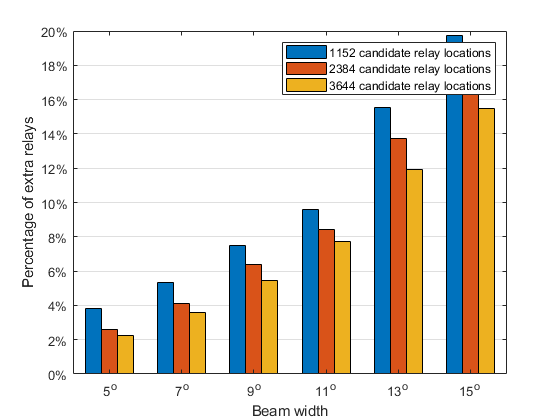

% Finding the number of groups and the number of bars in each group
ngroups = size(model_series, 1);
nbars = size(model_series, 2);
% Calculating the width for each bar group
groupwidth = min(0.8, nbars/(nbars + 1.5));
% Set the position of each error bar in the centre of the main bar
% Based on barweb.m by Bolu Ajiboye from MATLAB File Exchange
% for i = 1:nbars
%     % Calculate center of each bar
%     x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
%     errorbar(x, model_series(:,i), model_error(:,i), 'k', 'linestyle', 'none');
% end
% 
% fixedTotal_1/300
% fixedTotal_2/100

figure;
bw = 5:2:15;
% Data to be plotted as a bar graph
data_1 = (AvgRNum2Mbs300mLow-AvgRNum1MbsBench300mLow)./AvgRNum1MbsBench300mLow.*100;
data_2 = (AvgRNum2Mbs300mMed-AvgRNum1MbsBench300mMed)./AvgRNum1MbsBench300mMed.*100;
data_3 = (AvgRNum2Mbs300mHigh-AvgRNum1MbsBench300mHigh)./AvgRNum1MbsBench300mHigh.*100;
model_series = [data_1;data_2;data_3]';
%Data to be plotted as the error bars
% model_error = [avgNumRelayStd;avgNumRelayIdpStd;avgNumRelayStd2;avgNumRelayIdpStd2]';
% Creating axes and the bar graph
ax = axes;
h = bar(model_series,'BarWidth',1);
% Set color for each bar face
% h(1).FaceColor = 'blue';
% h(2).FaceColor = 'yellow';
% Properties of the bar graph as required
ax.YGrid = 'on';
ax.GridLineStyle = '-';
xticks(ax,[1 2 3 4 5 6]);
% Naming each of the bar groups
xticklabels(ax,{ '5^o', '7^o', '9^o', '11^o', '13^o', '15^o'});
ytickformat(ax, 'percentage');
% X and Y labels
xlabel ('Beam width');
ylabel ({'Percentage of extra relays'});
% Creating a legend and placing it outside the bar plot
lg = legend('1152 candidate relay locations','2384 candidate relay locations','3644 candidate relay locations','AutoUpdate','off');
% lg.Location = 'BestOutside';
lg.Orientation = 'vertical';
hold on;

% Finding the number of groups and the number of bars in each group
ngroups = size(model_series, 1);
nbars = size(model_series, 2);
% Calculating the width for each bar group
groupwidth = min(0.8, nbars/(nbars + 1.5));
% Set the position of each error bar in the centre of the main bar
% Based on barweb.m by Bolu Ajiboye from MATLAB File Exchange
% for i = 1:nbars
%     % Calculate center of each bar
%     x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
%     errorbar(x, model_series(:,i), model_error(:,i), 'k', 'linestyle', 'none');
% end
% 
% fixedTotal_1/300
% fixedTotal_2/100


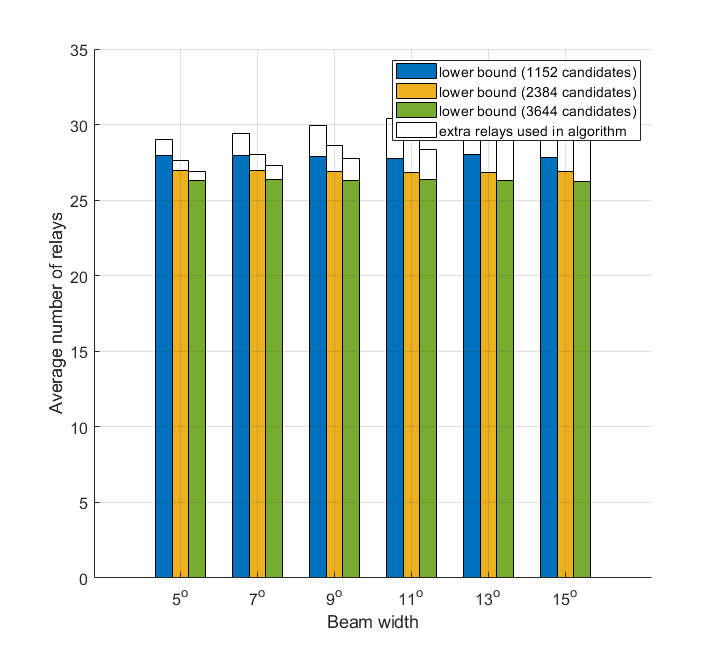

figure;

NumStacksPerGroup = 3; 
NumGroupsPerAxis = 6; 
NumStackElements = 2;

% labels to use on tick marks for groups 
groupLabels = { '5^o', '7^o', '9^o', '11^o', '13^o', '15^o' }; 
stackData = zeros(NumGroupsPerAxis,NumStacksPerGroup,NumStackElements);
stackData(:,1,1) = AvgRNum1MbsBench300mLow';
stackData(:,2,1) = AvgRNum1MbsBench300mMed';
stackData(:,3,1) = AvgRNum1MbsBench300mHigh';
stackData(:,1,2) = (AvgRNum2Mbs300mLow - AvgRNum1MbsBench300mLow)';
stackData(:,2,2) = (AvgRNum2Mbs300mMed - AvgRNum1MbsBench300mMed)';
stackData(:,3,2) = (AvgRNum2Mbs300mHigh - AvgRNum1MbsBench300mHigh)';
stackData = stackData.*21;

b = plotBarStackGroups(stackData, groupLabels); 
legend([b(1,1), b(2,1), b(3,1), b(1,2)], 'lower bound (1152 candidates)', 'lower bound (2384 candidates)', 'lower bound (3644 candidates)', 'extra relays used in algorithm');     
set(gca,'FontSize',12) 
set(gcf,'Position',[100 100 720 650]) 
grid on 
set(gca,'Layer','top') % put grid lines on top of stacks
xlabel ('Beam width');
ylabel ({'Average number of relays'});